# **A Paired Sample Analysis of Google Maps Bus Time Estimates in Singapore**

**Author: Alex Ouyang**

Please note that in order to run the following code, the 'Statistics and Machine Learning toolbox' must be installed. 

## Background

Public transport systems in Singapore play a vital role in transporting millions of people a day. It's efficiency has been, and continues to be a major reason as to why Singapore and it's economy continues to grow at an astounding rate. People often rely on online services to gather information about their public transport. One popular service that is often used is Google Maps. This statistical analysis aims to compare Google Maps' estimated bus travel durations with the actual travel durations recorded during the same journey to determine whether these estimates are accurate and reliable. 

The process began at the bus stop, where estimated bus durations from Google Maps were noted 5 minutes before the bus arrived. As soon as the bus arrived and came to a complete halt, a timer was started. This timer continued until the destination had been reached and the bus came to a complete stop. The time was then noted. This was repeated twenty eight times across an approximate one and a half week duration. 

It is noted that Google Maps estimates are rounded to the nearest minute, however actual travel durations were given to the nearest second. Both sets of data are given in seconds. It is also noted that most of the bus routes are from the 196 bus from UTown to Clementi mall (as I tend to find myself taking this bus route often). Thus there may be some bias, and these results are unlikely to be a completely accurate representation of Singapore as a whole. 

### Loading Data

Estimated and actual travel durations are given in seconds.

estimated_travel_durations = [
    660, 780, 660, 780, 660, 840, 660, 960, 660, ...
    720, 780, 720, 840, 660, 840, 660, 900, 720, ...
    660, 840, 660, 780, 720, 900, 720, 960, 720, 780
];

actual_travel_durations = [
    687, 720, 582, 825, 692, 833, 642, 831, 671, ...
    691, 783, 669, 841, 669, 818, 657, 917, 733, ...
    672, 849, 703, 788, 692, 861, 685, 937, 732, 813
];

### Boxplot Comparison Visualisation

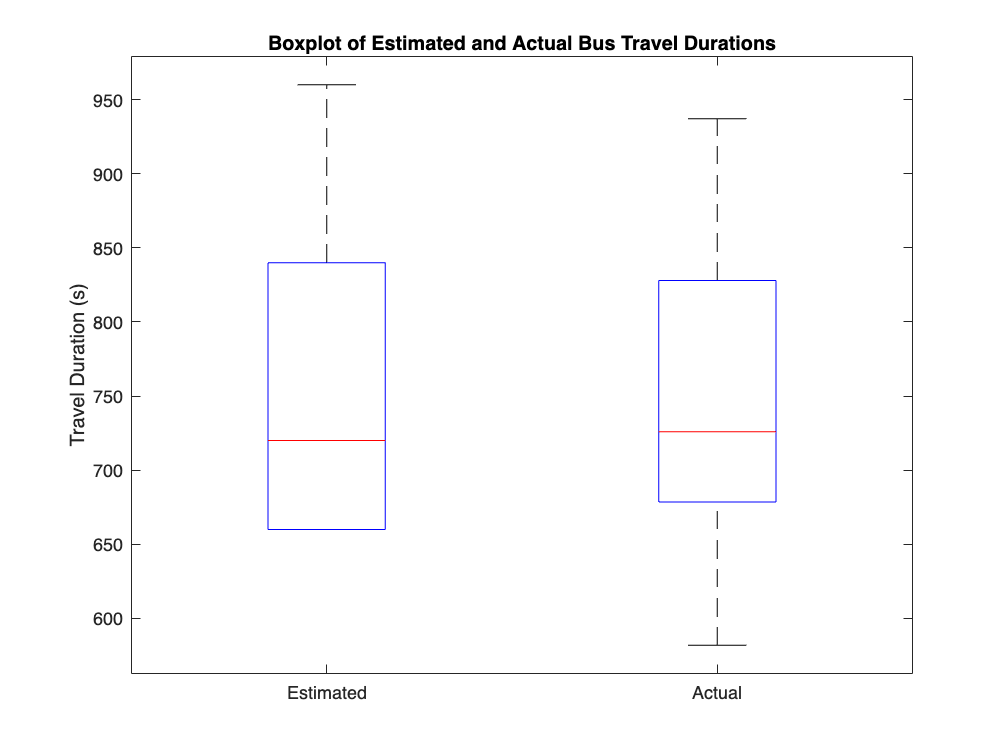

group = [ones(1, length(estimated_travel_durations)), ...
    2 * ones(1, length(actual_travel_durations))];

figure(1);
boxplot([estimated_travel_durations, actual_travel_durations], group, ...
    'Labels', {'Estimated', 'Actual'});
title('Boxplot of Estimated and Actual Bus Travel Durations');
ylabel('Travel Duration (s)');

The medians of the estimated travel duration and actual travel durations are approximately equivalent at 720 seconds. However, there appears to be more variation in the actual travel durations as it has an approximate range of 350 seconds as opposed to the estimated travel durations which have an approximate range of 300 seconds. Overall both estimated and actual durations appear to be slightly right skewed. 

## Histogram Visualisation

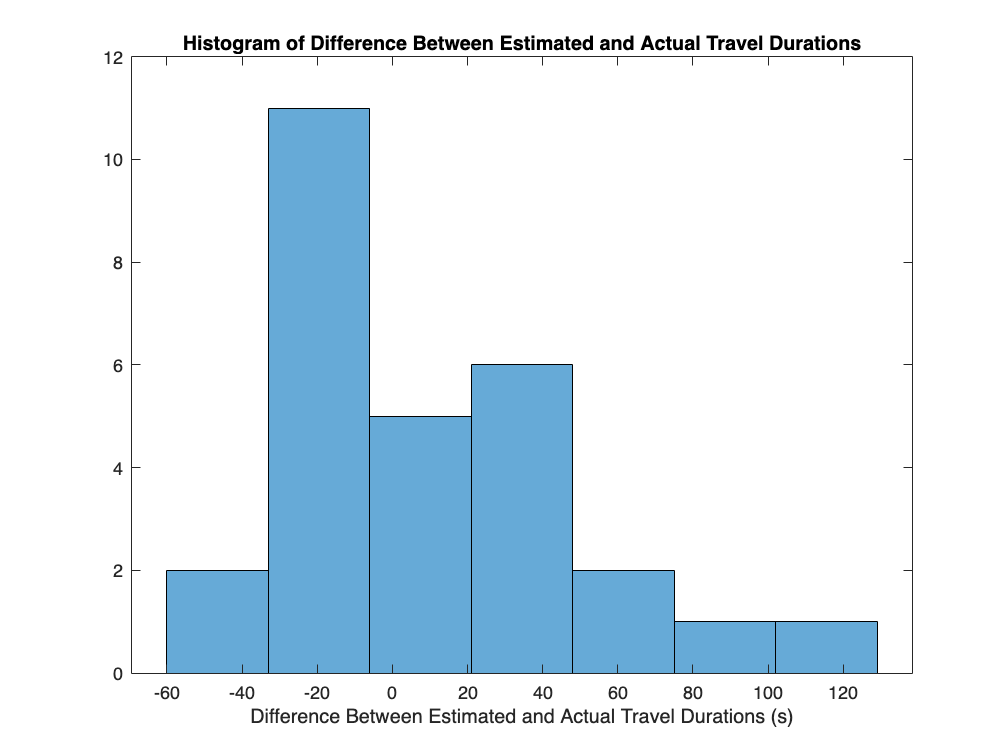

travel_duration_differences = estimated_travel_durations - actual_travel_durations;

figure(2);
histogram(travel_duration_differences, 7);
title('Histogram of Difference Between Estimated and Actual Travel Durations');
xlabel('Difference Between Estimated and Actual Travel Durations (s)');

The histogram of the difference between the two samples appears to be slightly right-skewed. Because of this, normality is not assumed, however the Central Limit Theorem can be weakly invoked (as the sample size is almost equivalent to 30) and thus the distribution of the sample means can be 'weakly assumed' as normal. Note that this is a strong assumption as a sample size close to, equal to or larger than 30 does not necessarily mean that the distribution of sample means is normally distributed, however it can be considered a general rule of thumb.

## Quantile-Quantile Plot Visualisation

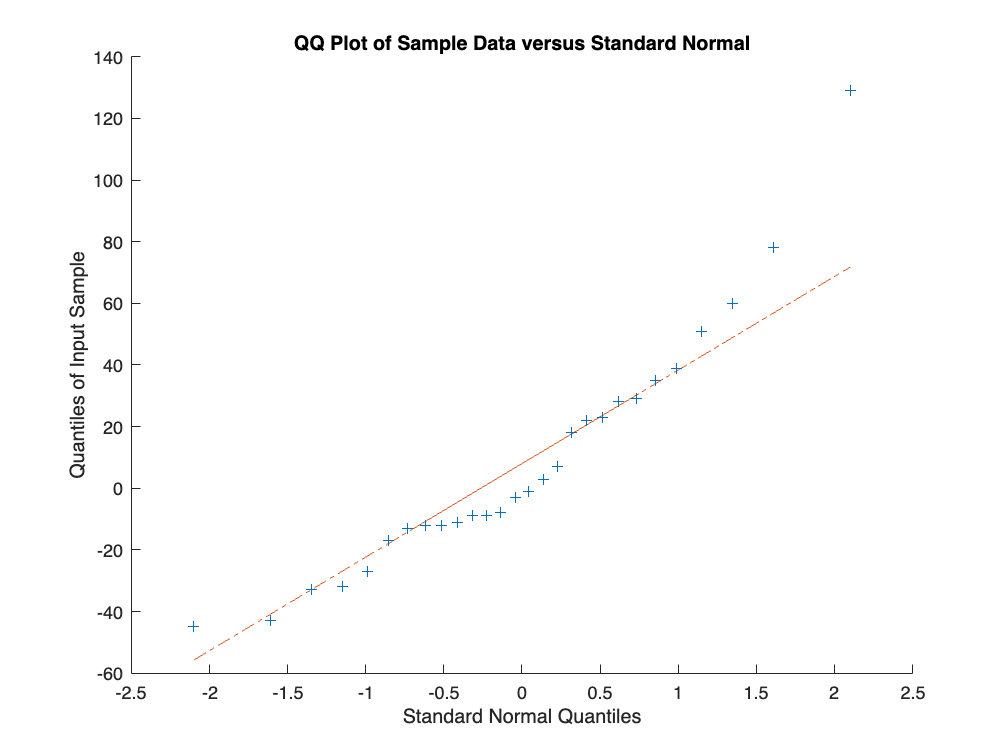

figure(3);
qqplot(travel_duration_differences);

The Quantile-Quantile plot further proves that the data is slightly right-skewed.

## Boxplot Visualisation of Difference Between Estimated and Actual Travel Durations

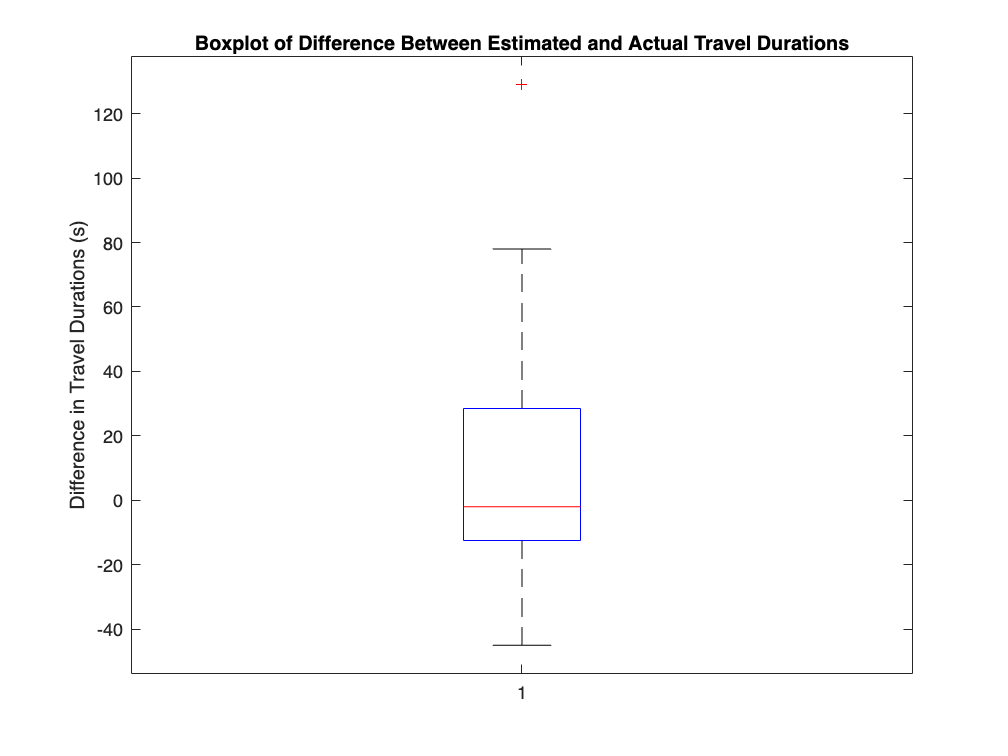

figure(4);
boxplot(travel_duration_differences);
title('Boxplot of Difference Between Estimated and Actual Travel Durations');
ylabel('Difference in Travel Durations (s)');

This boxplot of the difference between estimated and actual travel durations simply confirms that our data is indeed slightly skewed to the right.

### Paired Sample T-Test

A two-tailed paired sample t-test is performed.

[h, p, ci, stats] = ttest(estimated_travel_durations, actual_travel_durations);

if h == 0
    disp('The null hypothesis cannot be rejected: No significant difference.');
else
    disp('The null hypothesis is rejected: There is a significant difference.');
end

The null hypothesis cannot be rejected: No significant difference.


fprintf('p-value: %.4f\n', p);

p-value: 0.2376


fprintf('T-statistic: %.4f\n', stats.tstat);

T-statistic: 1.2077


fprintf('Degrees of Freedom: %.0f\n', stats.df);

Degrees of Freedom: 27


fprintf('95% Confidence Interval: [%.4f, %.4f]\n', ci);

95

The results of the paired-sample t-test illustrate that under the null hypothesis which states that there is no statistically significant difference between the means of estimated and actual travel durations by bus, there is not enough evidence to reject the null hypothesis as the p-value obtained is equal to 0.2376, which is indeed larger than our significance level of 0.05. 